[y, Fs] = audioread("C:\Users\Rebecka\Documents\Liu\Kurser\Ljudteknik\TNM103-Ljudteknik\AnalogRytm_120BPM.wav")

y =     0.0016    0.0021
    0.0050    0.0066
    0.0029    0.0039
    0.0224    0.0291
    0.0646    0.0848
    0.0324    0.0435
   -0.0210   -0.0270
   -0.0572   -0.0750
   -0.0881   -0.1159
   -0.1141   -0.1502


Fs = 44100

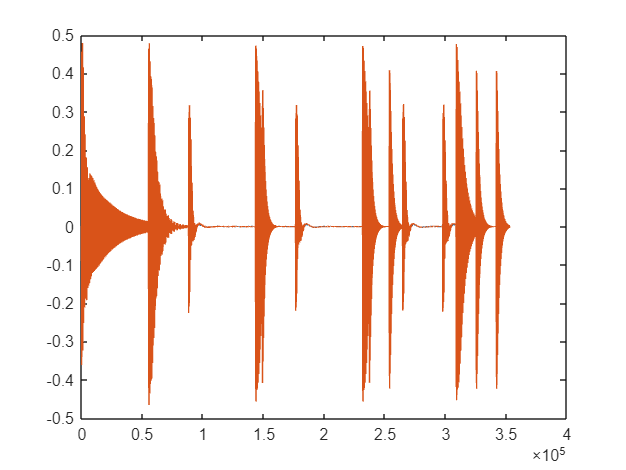

[z, FsEKO] = audioread("C:\Users\Rebecka\Documents\Liu\Kurser\Ljudteknik\TNM103-Ljudteknik\TimeFactor_RE501_120BPM.wav");
plot(y);

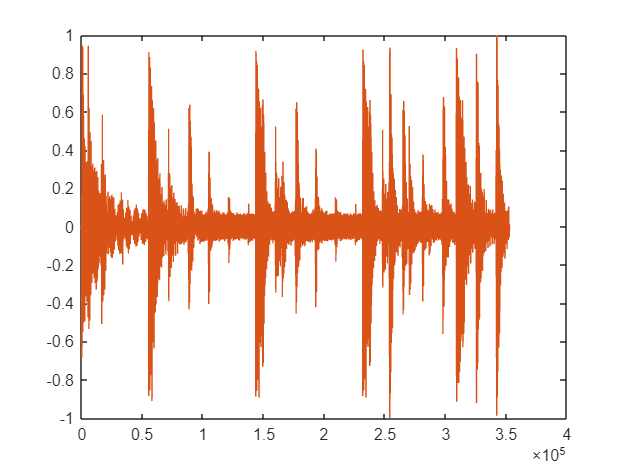

plot(z);

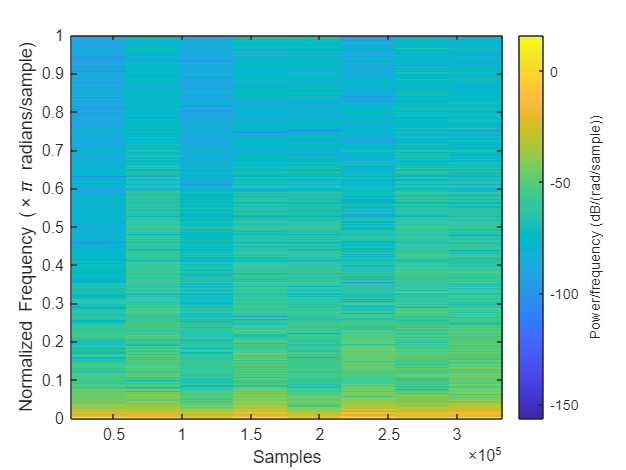


% Spektogram
%(spectrogram(y, window, noverlap, nfft))
(spectrogram(abs(y(:, 1)), 'yaxis'))

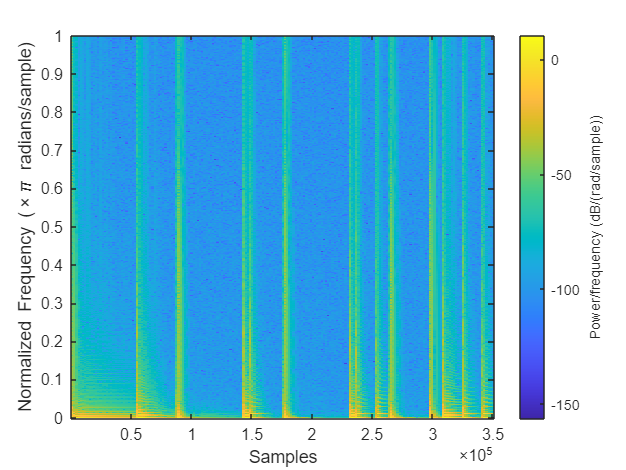

(spectrogram(abs(y(:, 1)), 2000, 200, 1000, 'yaxis'))

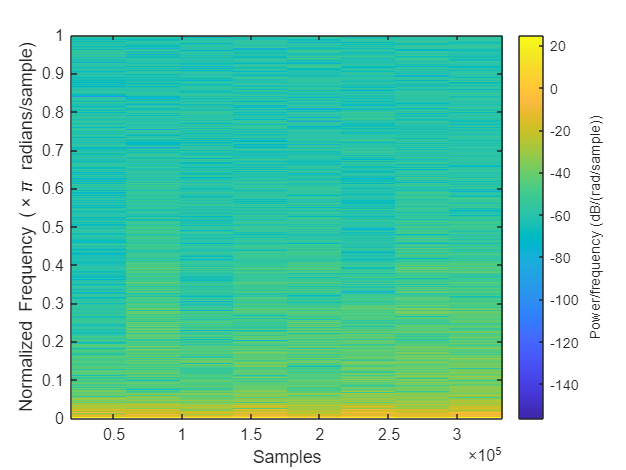

% Eko
(spectrogram(abs(z(:, 1)), 'yaxis'))

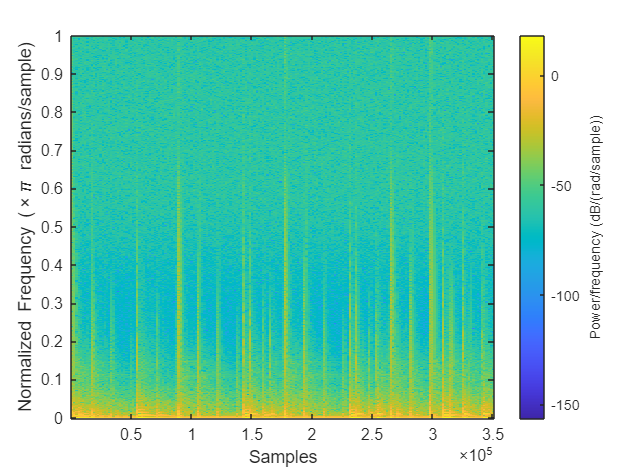

(spectrogram(abs(z(:, 1)), 2000, 200, 1000, 'yaxis'))

% Delay
nollor = zeros(Fs/4, 1);
y1 = y(:, 1);

y1forlangd = [ y1 ; nollor ; nollor ; nollor ; nollor];
delay1 = [ nollor ; y1 ; nollor ; nollor ; nollor];
delay2 = [nollor ; nollor ; y1 ; nollor ; nollor];
delay3 = [nollor ; nollor ; nollor ; y1 ; nollor];
delay4 = [nollor ; nollor ; nollor ; nollor ; y1];


summa = (y1forlangd + delay1.*0.8 + delay2.*0.3 + delay3.*0.1 + delay4.*0.01);
sound(summa, Fs)

% Reverb
numberOfAllpass = 3;
reverbTime = 20;
reverbGain = 0.7;
for i = 0:numberOfAllpass-1
    reverbLength = ceil((reverbTime/1000) * Fs / (3^i));
    signalForReverb = [signalForReverb ; zeros(abs(reverbTime/100) * Fs, 2)];
    signalForReverb = schroederAllpass(signalForReverb, reverbLength, reverbGain, Fs);
end